Textfile = load("STM32Output.txt")

Textfile =     0.0800
    0.0700
    0.0900
    0.0400
    0.0900
    0.0900
    0.0400
    0.1200
    0.0800
    0.1000


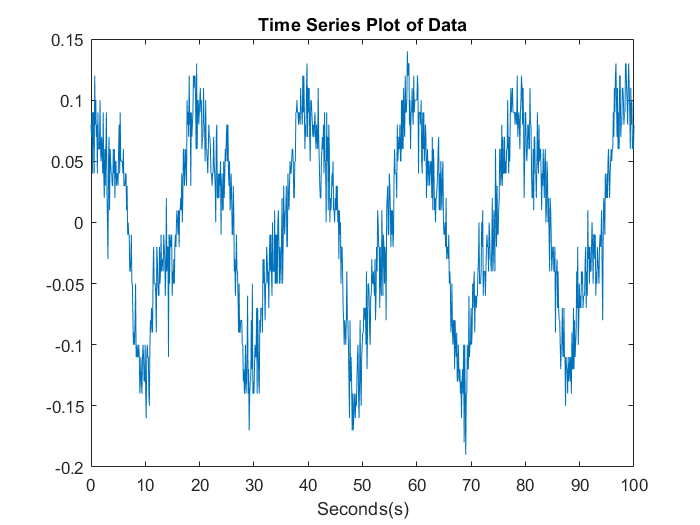

writematrix(Textfile, "STM32Output.csv");
timeSeriesData = readtable("STM32Output.csv");


N =  1024 - 1; 
timeSeriesData = timeSeriesData{:, 1}; %data is symmetric, *2 to account for contribution of other half 
fs = 100;
time = fs*(0:(N))/N;

plot(time(1:1024), timeSeriesData(1:1024)); %only plotting the real side of the dataset 
title("Time Series Plot of Data");
xlabel("Seconds(s)");